# Epipolar rectification

We observe that when $C$ is in the focal plane of the conjugated camera, its epipole is at infinity and the epipolar lines are all parallel; the same goes with $C'$. When both $C$ and $C'$ are in the conjugate focal plane (so when the baseline $b=CC'$ is in both the focal planes) then both the epipoles are at infinity and all the epipolar lines are parallel. Basically, this is the case that occurs when we take two images from an horizontally sliding camera.

This setup is very convenient when calculating **correspondence** because if all epipolar lines are parallel, then the correspondences lie on the same **scan-line**, which simplifies a lot the problem. In order to induce this setup, given the two PPMs $P_0$ and ${P'}_0$, assuming they have the same intrinsic matrix $K$, we keep the optic centers $C$ and $C'$ but align their rotation matrices to point in the same direction, perpendicular to the baseline $b$.

Formally, to simplify the derivation, we exploit the equation of the cartesian optic center $\tilde{C} = -Q^{-1}q = -R^{-1}t$, which allows us to rewrite $t=-R^{-1}\tilde{C}$ inside the PPMs. Since we want the same rotation $R$ in both the resulting PPMs, we can write the desired equations as 

$P_n=K[R|-R\tilde{C}]$    and    ${P_n}'=K[R|-R\tilde{C'}]$

Now, $K$ is known and, as aforementioned, $\tilde{C}$ is easily obtained via $P_0=\left[\matrix{Q_0 & q_0}\right]$ using the equation $\tilde{C}=-{Q_0}^{-1}q_0$, and the same goes for $\tilde{C'}$, so the only missing term is of course the rotation matrix $R$. Here we force the following conditions:

- the new $x$ axis must be parallel to the baseline $b$, so $r_x = \frac{\tilde{C}-\tilde{C'}}{||\tilde{C}-\tilde{C'}||}$;

- the new $y$ axis must be orthogonal to the new $x$ axis and an arbitrary versor $k$, which we choose to be the old $z$ axis so to keep pointing at the same height. In the end, $y=k \times r_x$;

- the new $z$ axis must complete the right-hand rule, so $r_z = r_x \times r_y$.

As we can observe, when the two cameras are simply displaced over the $x$ axis, the cross product for $r_y$ fails, returning $0$. This is expected, since the rectification is basically the enhancement and isolation of the horizontal displacement, and here we don't have one, so everything collapses.

Now that we have found $R$, in order to "capture" the new images using the new PPMs we need to warp the old images by a certain transformation matrix that performs $P_0 \rightarrow P_n$ (and ${P_0}' \rightarrow {P_n}'$). Since we know that the projection $m_0 \simeq P_0 M$ has optic ray $\tilde{M} = \tilde{C} + \lambda_0 {Q_0}^{-1}m_0$ (same goes for ${P_0}'$), we can exploit the fact that for the new cameras the $M$ point will remain the same, so for $m_n \simeq P_n M$ we will have $\tilde{M} = \tilde{C} + \lambda_n {Q_n}^{-1}m_n$. With this in mind, we can write


$$\tilde{C} + \lambda_0 {Q_0}^{-1}m_0 = \tilde{C} + \lambda_n {Q_n}^{-1}m_n \qquad \Longrightarrow \qquad m_n \simeq Q_n{Q_0}^{-1}m_0$$


and conclude that $T=Q_n{Q_0}^{-1}$ and $T'={Q_n}'{{Q_0}'}^{-1}$ are the **collineations** that perform $P_0 \rightarrow P_n$ and ${P_0}' \rightarrow {P_n}'$ respectively. The last thing now is to perform **image warping** of the original images using those two matrices.

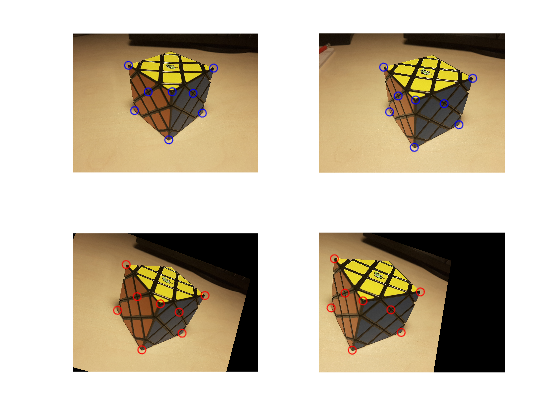

addpath('../0.utils/');
addpath('../5.epipolar_geometry/');

calib_results_folder = '../0.calib_results';
stereo_file = 'stereo-cube-img_2+img_1.mat';

stereo = load(fullfile(calib_results_folder, stereo_file));

% optic centers of the cameras already in homogeneous coordinates ( C(4) == 1 )
CL = stereo.L_camera.C(1:3);
CR = stereo.R_camera.C(1:3);

rx = (CR - CL) ./ norm(CR - CL);
ry = cross(stereo.R_camera.R(3,:)', rx);
ry = ry./norm(ry);
rz = cross(rx, ry);
rz = rz./norm(rz);

R = [rx'; ry'; rz'];
tL = -R*CL;
tR = -R*CR;


% left camera rectification
stereo.rect.L_camera = stereo.L_camera;
stereo.rect.L_camera.P = stereo.L_camera.K*[R tL];
stereo.rect.L_camera.G = [R tL; zeros(1,3) 1];
stereo.rect.L_camera.R = R;
stereo.rect.L_camera.t = tL;
stereo.rect.L_camera.C = CL;
stereo.rect.L_camera.m = project(stereo.rect.L_camera.P, stereo.rect.L_camera.M);

% right camera rectification
stereo.rect.R_camera = stereo.R_camera;
stereo.rect.R_camera.P = stereo.R_camera.K*[R tR];
stereo.rect.R_camera.G = [R tR; zeros(1,3) 1];
stereo.rect.R_camera.R = R;
stereo.rect.R_camera.t = tR;
stereo.rect.R_camera.C = CR;
stereo.rect.R_camera.m = project(stereo.rect.R_camera.P, stereo.rect.R_camera.M);

% add the rectified setup info
stereo.rect.R = R;
stereo.rect.TL = stereo.rect.L_camera.P(1:3,1:3) / stereo.L_camera.P(1:3,1:3);  % A/B == A*inv(B)
stereo.rect.TR = stereo.rect.R_camera.P(1:3,1:3) / stereo.R_camera.P(1:3,1:3);

% find the new fundamental matrix
stereo.rect.setup = fundamental(stereo.rect.L_camera.P, stereo.rect.R_camera.P);


% rectify images
stereo.rect.L_camera.image(:,:,1) = imwarp(stereo.L_camera.image(:,:,1), stereo.rect.TL);
stereo.rect.L_camera.image(:,:,2) = imwarp(stereo.L_camera.image(:,:,2), stereo.rect.TL);
stereo.rect.L_camera.image(:,:,3) = imwarp(stereo.L_camera.image(:,:,3), stereo.rect.TL);

stereo.rect.R_camera.image(:,:,1) = imwarp(stereo.R_camera.image(:,:,1), stereo.rect.TR);
stereo.rect.R_camera.image(:,:,2) = imwarp(stereo.R_camera.image(:,:,2), stereo.rect.TR);
stereo.rect.R_camera.image(:,:,3) = imwarp(stereo.R_camera.image(:,:,3), stereo.rect.TR);


[~, rect_stereo_setup_filename, ~] = fileparts(stereo_file);
rect_stereo_setup_filename = sprintf('%s-rect.mat', rect_stereo_setup_filename);
rect_stereo_setup_path = fullfile(calib_results_folder, rect_stereo_setup_filename);
save(rect_stereo_setup_path, '-struct', 'stereo');


% show rectified images
subplot(2,2,1), imshow(stereo.L_camera.image);
subplot(2,2,1), hold on, scatter(stereo.L_camera.m(1,:), stereo.L_camera.m(2,:),'b');
subplot(2,2,2), imshow(stereo.R_camera.image);
subplot(2,2,2), hold on, scatter(stereo.R_camera.m(1,:), stereo.R_camera.m(2,:),'b');
subplot(2,2,3), imshow(stereo.rect.L_camera.image);
subplot(2,2,3), hold on, scatter(stereo.rect.L_camera.m(1,:), stereo.rect.L_camera.m(2,:),'r');
subplot(2,2,4), imshow(stereo.rect.R_camera.image);
subplot(2,2,4), hold on, scatter(stereo.rect.R_camera.m(1,:), stereo.rect.R_camera.m(2,:),'r');


clear rx ry rz R tL tR CL CR ...
    calib_results_folder stereo_file rect_stereo_setup_filename rect_stereo_setup_path;

## Test the rectified setup

After having created the rectified setup, we place the two images one next to the other and, given a point from one of the two, we plot the epipole line onto the other. We should now see just parallel lines.

% load if just created the setup
if exist('stereo','var') == 0
    % otherwise set the desired setup
    stereo = load('../0.calib_results/stereo-cube-img_2+img_1.mat');
end

show_epipolar_lines(stereo.rect);

## Show the new rotation

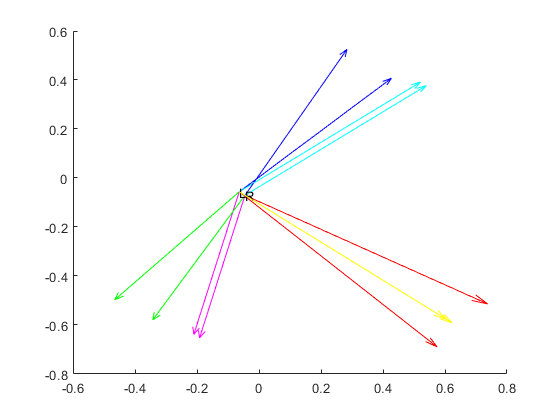

figure;
hold on;

% show left transform
x = stereo.L_camera.C(1);
y = stereo.L_camera.C(2);
z = stereo.L_camera.C(3);
text(x,y,z,'L');

X = stereo.L_camera.G(1,1:3); 
Y = stereo.L_camera.G(2,1:3);
Z = stereo.L_camera.G(3,1:3);
quiver3(x,y,z,X(1),X(2),X(3),'Color','r')
quiver3(x,y,z,Y(1),Y(2),Y(3),'Color','g')
quiver3(x,y,z,Z(1),Z(2),Z(3),'Color','b')

X = stereo.rect.L_camera.G(1,1:3); 
Y = stereo.rect.L_camera.G(2,1:3);
Z = stereo.rect.L_camera.G(3,1:3);
quiver3(x,y,z,X(1),X(2),X(3),'Color','y')
quiver3(x,y,z,Y(1),Y(2),Y(3),'Color','m')
quiver3(x,y,z,Z(1),Z(2),Z(3),'Color','c')


% show right transform
x = stereo.R_camera.C(1);
y = stereo.R_camera.C(2);
z = stereo.R_camera.C(3);
text(x,y,z,'R');

X = stereo.R_camera.G(1,1:3); 
Y = stereo.R_camera.G(2,1:3);
Z = stereo.R_camera.G(3,1:3);
quiver3(x,y,z,X(1),X(2),X(3),'Color','r')
quiver3(x,y,z,Y(1),Y(2),Y(3),'Color','g')
quiver3(x,y,z,Z(1),Z(2),Z(3),'Color','b')

X = stereo.rect.R_camera.G(1,1:3); 
Y = stereo.rect.R_camera.G(2,1:3);
Z = stereo.rect.R_camera.G(3,1:3);
quiver3(x,y,z,X(1),X(2),X(3),'Color','y')
quiver3(x,y,z,Y(1),Y(2),Y(3),'Color','m')
quiver3(x,y,z,Z(1),Z(2),Z(3),'Color','c')


clear x y z X Y Z